%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%    ANTI-WINDUP DESIGN & UNSTABLE LIMIT-CYCLE
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear 
close all

% Question 1   - PID controller design
% -------------------------------------
% >>> Insert your code here to find the values Kp, Ki, Kd below <<<<

% Check results
Ki=0.5372; Kp = 1.4968; Kd = 1.6797; % to be found ! 
refmag=1; Tsim=10; 
[a,b,c,d]=linmod('scheme1_sim'); % saturation replaced by gain=1 when linearizing
damp(a)

                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
 -2.69e+00                 1.00e+00       2.69e+00          3.72e-01    
 -1.00e+00                 1.00e+00       1.00e+00          9.99e-01    
 -7.07e-01 + 7.07e-01i     7.07e-01       1.00e+00          1.41e+00    
 -7.07e-01 - 7.07e-01i     7.07e-01       1.00e+00          1.41e+00    


%the fourth pole corresponds to the integrator - actuator

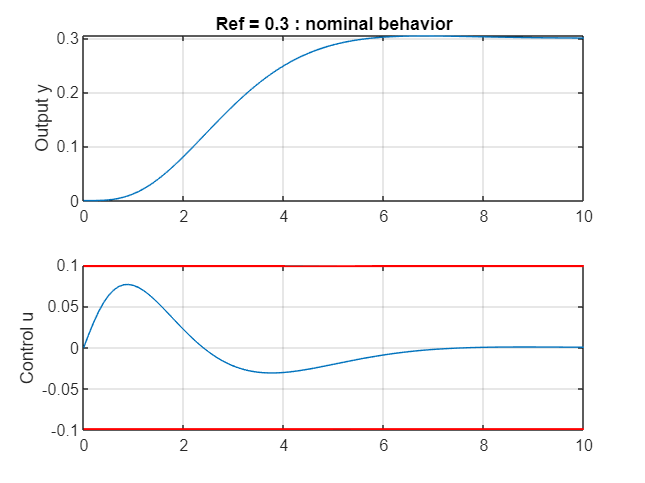

%% Question  2 - Simulation-based analysis of saturation effects
% ---------------------------------------------------------------

% a) nominal case : saturation not active
refmag=0.3;
Tsim=10;
[t,x,y]=sim('scheme1_sim');
figure(1); clf; 
subplot(211); plot(t,y(:,1)); grid; ylabel('Output y');
title('Ref = 0.3 : nominal behavior');
subplot(212); plot(t,y(:,2)); hold on; grid; ylabel('Control u');
plot([0 Tsim],[0.1 0.1],'r','LineWidth',2);
plot([0 Tsim],-[0.1 0.1],'r','LineWidth',2);

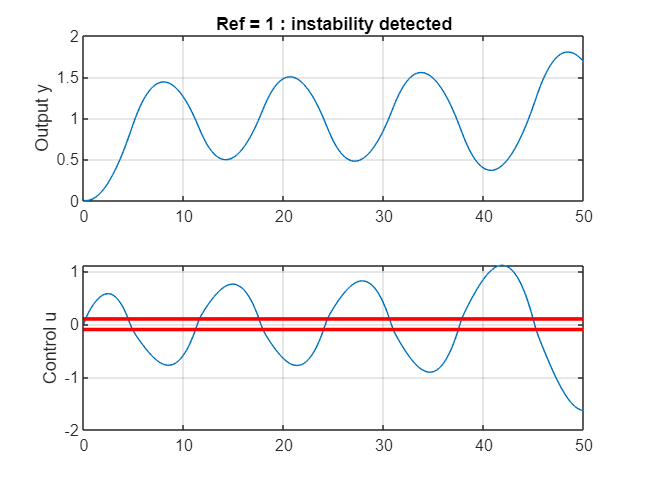


% b) unstable case : saturation highly active
refmag=1;
Tsim=50;
[t,x,y]=sim('scheme1_sim');
figure(2); clf; 
subplot(211); plot(t,y(:,1)); grid; ylabel('Output y');
title('Ref = 1 : instability detected');
subplot(212); plot(t,y(:,2)); hold on; grid; ylabel('Control u');
plot([0 Tsim],[0.1 0.1],'r','LineWidth',2);
plot([0 Tsim],-[0.1 0.1],'r','LineWidth',2);

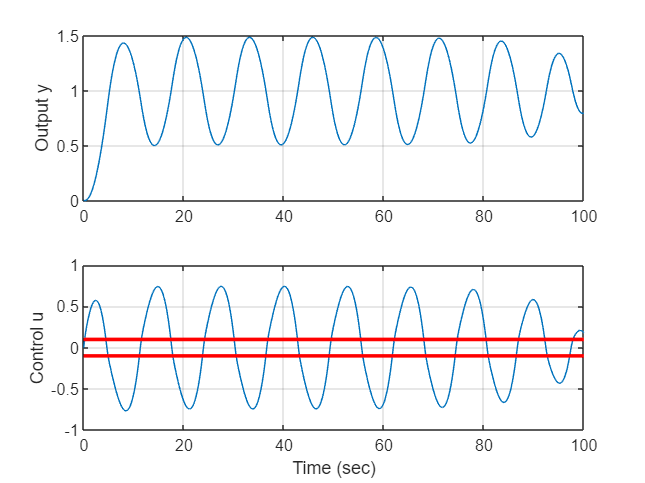

% c) critical case : limit-cycle ?
refmag=0.99759;
Tsim=100;
[t,x,y]=sim('scheme1_sim');
figure(3); clf; 
subplot(211); plot(t,y(:,1)); grid;  ylabel('Output y');
subplot(212); plot(t,y(:,2)); hold on; grid; ylabel('Control u');
xlabel('Time (sec)');
plot([0 Tsim],[0.1 0.1],'r','LineWidth',2);
plot([0 Tsim],-[0.1 0.1],'r','LineWidth',2);

Nature - oscillatory

Pulsation - 1/(39.9-27.3) = 0.0794 Hz = 0.53 rad/s

Magnitude - 0.74

% d) limit-cycle characteristics
% x0sim = ? , wcsim = ?
% omega = 0.53
% 



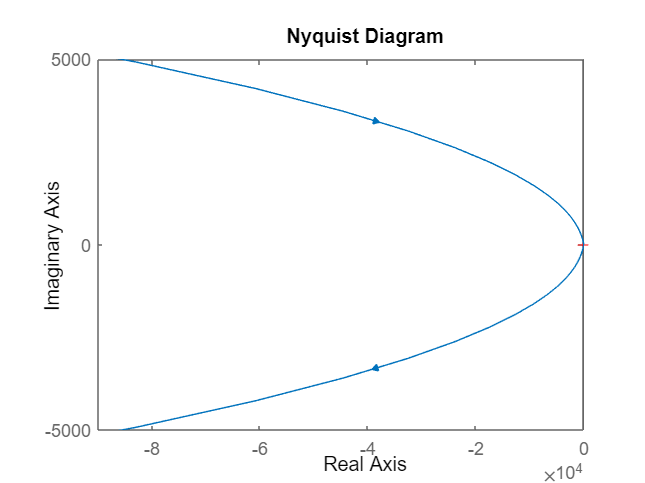

%% Question  3 - Describing function analysis
% --------------------------------------------

% a) Simulink file : scheme1_analysis to be derived from scheme1_sim
[a,b,c,d]=linmod('scheme1_analysis');
sys=-ss(a,b,c,d); % M(s) viewed by the saturation with negative feedback
% we remove the saturation signal, and put a - sign, which is what the
% saturation will see, since it is a negative feedback.
nyquist(sys)

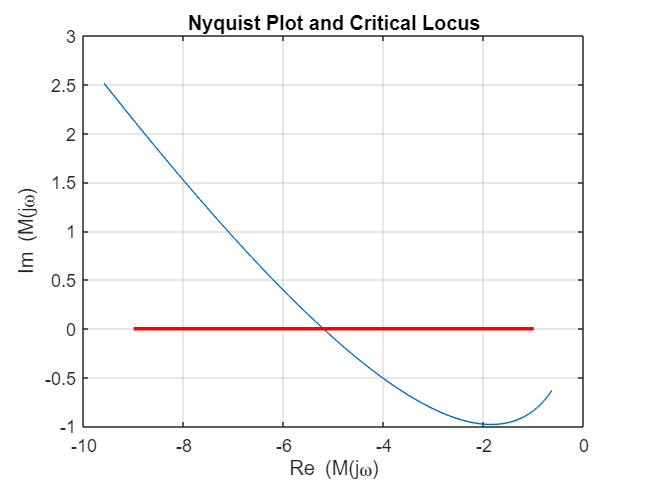

% b) Nyquist plot and critical locus
om_min=0.4;
om_max=1.8;
omeg=[om_min:0.01:om_max]; % no need to cover all frequencies
[re,im]=nyquist(sys,omeg);
re=squeeze(re); im=squeeze(im);
figure(4); clf; plot(re,im); grid; hold on;
plot([-9 -1],[0 0],'r','LineWidth',2);
xlabel('Re (M(j\omega)');
ylabel('Im (M(j\omega)');
title('Nyquist Plot and Critical Locus');

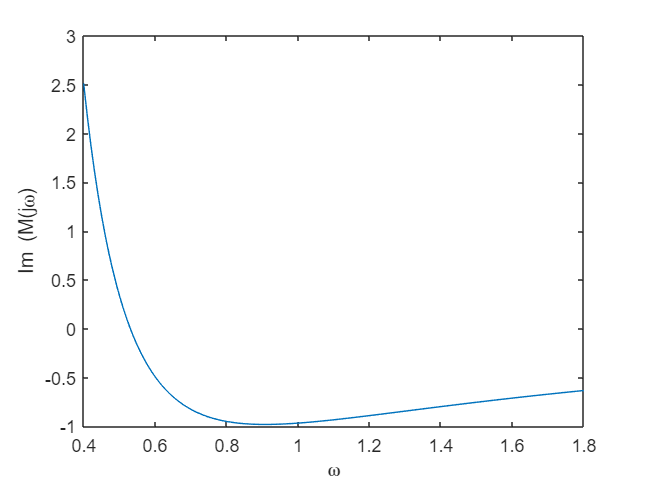

figure;
plot(omeg, im)
xlabel('\omega');
ylabel('Im (M(j\omega)')

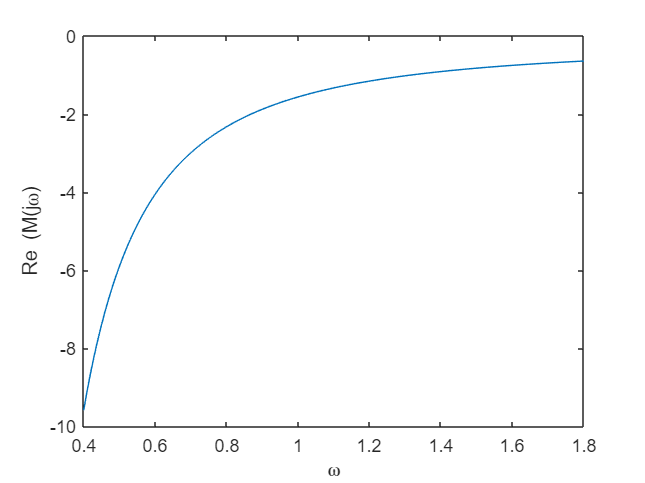

figure;
plot(omeg, re)
xlabel('\omega')
ylabel('Re (M(j\omega)');

%the point at which im = 0, gives w = 0.53 - pulsation of the limit cycle
%Re = -5.22; x0 = 0.6646
% c) LC chracateristics : x0DFA = ? , wcDFA = ?
% L = 0.1


% d) Ratio R = |M(3j*omc)/M(j*omc)| = ?
% comments ?
% 3*omega = 1.59; Re = 0.759; x0(3w) = (0.759*4*0.1)/(pi) = 0.0966
R = 0.0966/0.6646   

R = 0.1454

%% Question  4 - Anti-windup design
% ---------------------------------

% a) Simulink file : scheme1_analysis_aw to be defined
% b) Nyquist plots for different values of Kaw
% c) Simulation with anti-windup Kaw > Kawc




